# DIO - Clear Faults and display Fault status, using DIO component

In this exercise, we are going to use Digital Input Output component (**Dio**) for:

- **ClearFault** signal, using the **SW7** push button;

- Indicate **OverLoad** via the **D33 LED**;

- Indicate **OverCurrent** via the **D35 LED**.

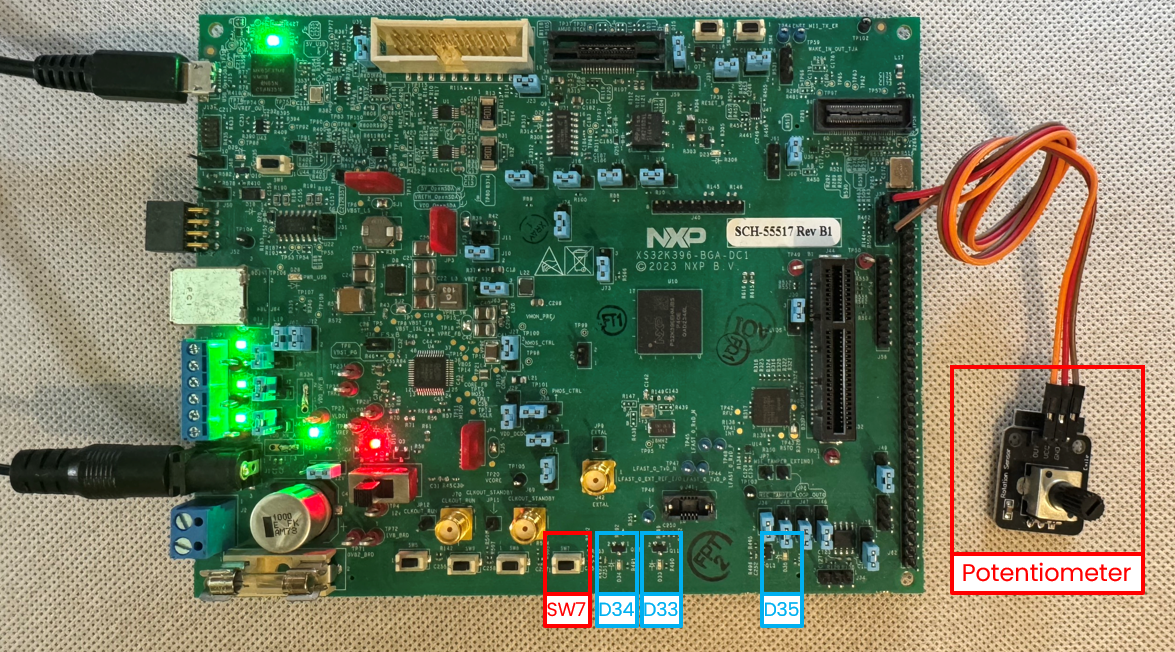

The **SW7** push button is used as a signal for clearing an existing fault, as described in the previous exercises.

When the **D33** and **D35** LEDs are turned off, it indicates there are no faults, meaning the measured current value is in the range of 0 A - 5 A. 

When the **D33** LED is turned ON, it indicates the OverLoad fault active.

When the **D35** LED is turned ON, it indicates the OverCurrent fault active.

According to the board schematics, the Push buttons and the LEDs are connected to the following MCU pins:

- **SW7 - PTG2**

- **D33 - PTD5**

- **D34 - PTD4**

- **D35 - PTH7**

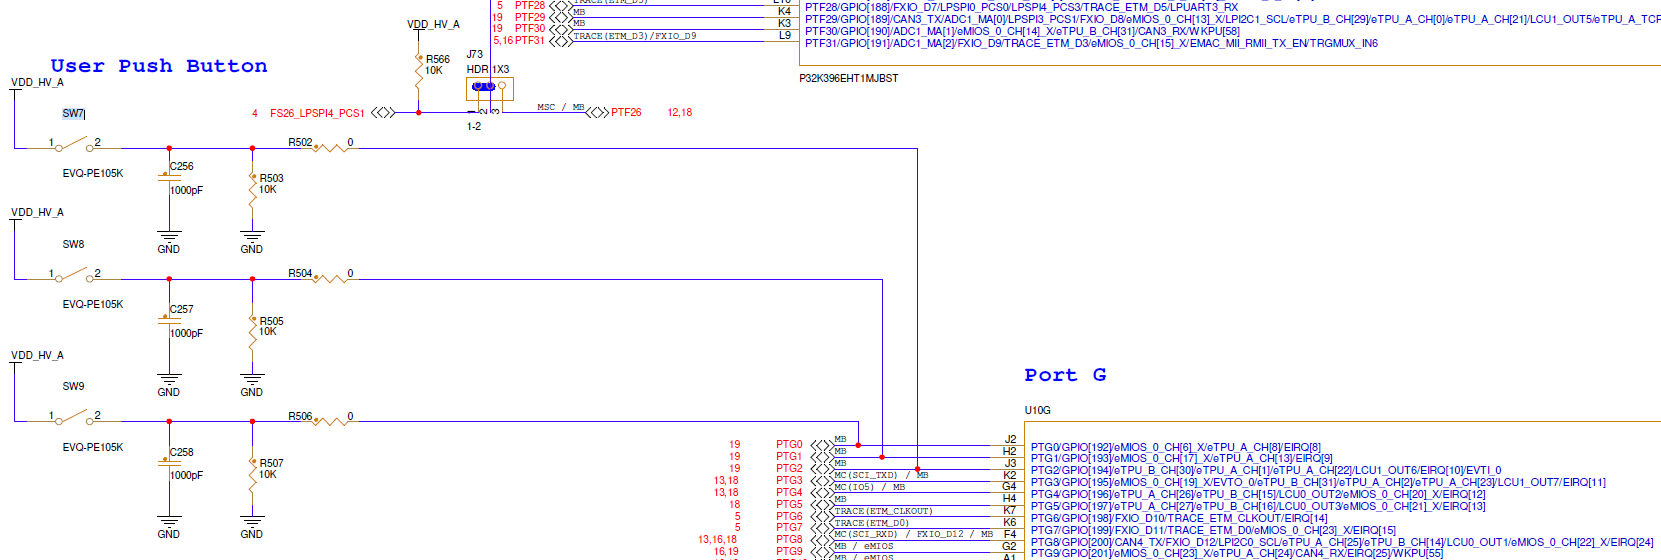

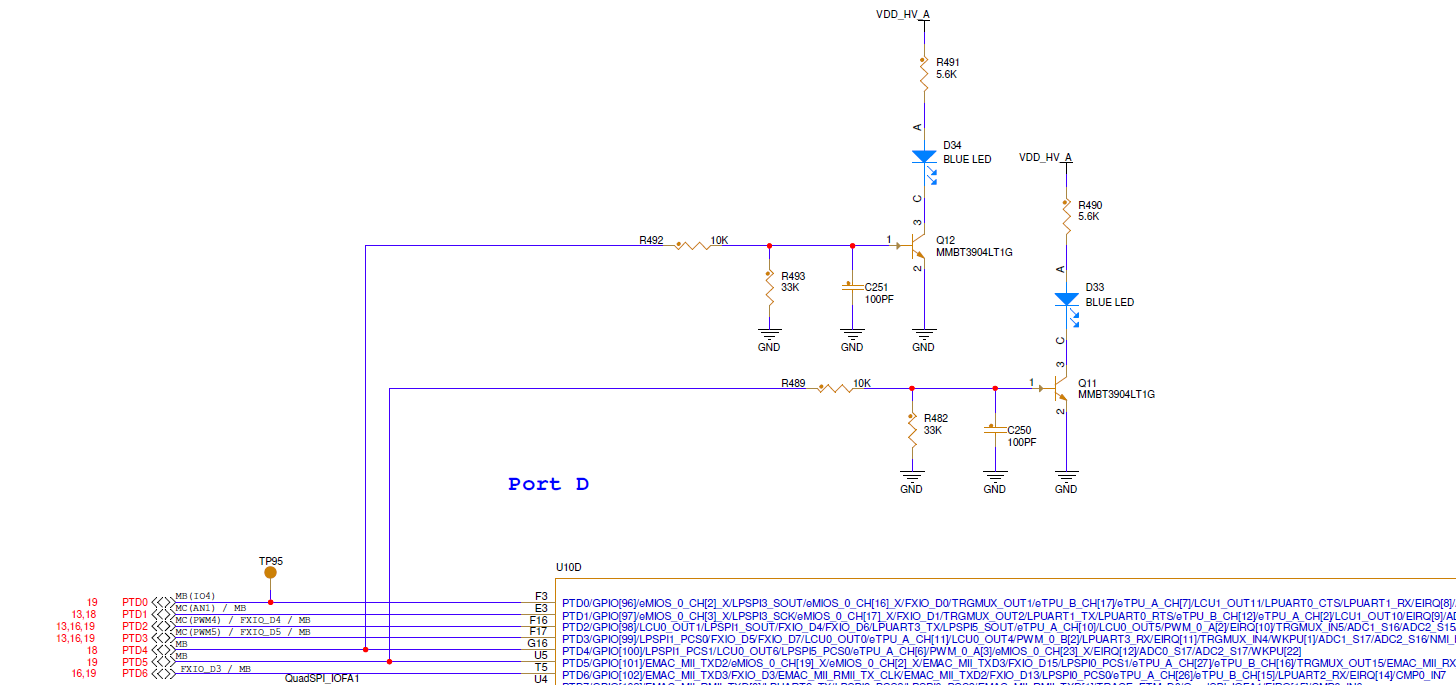 

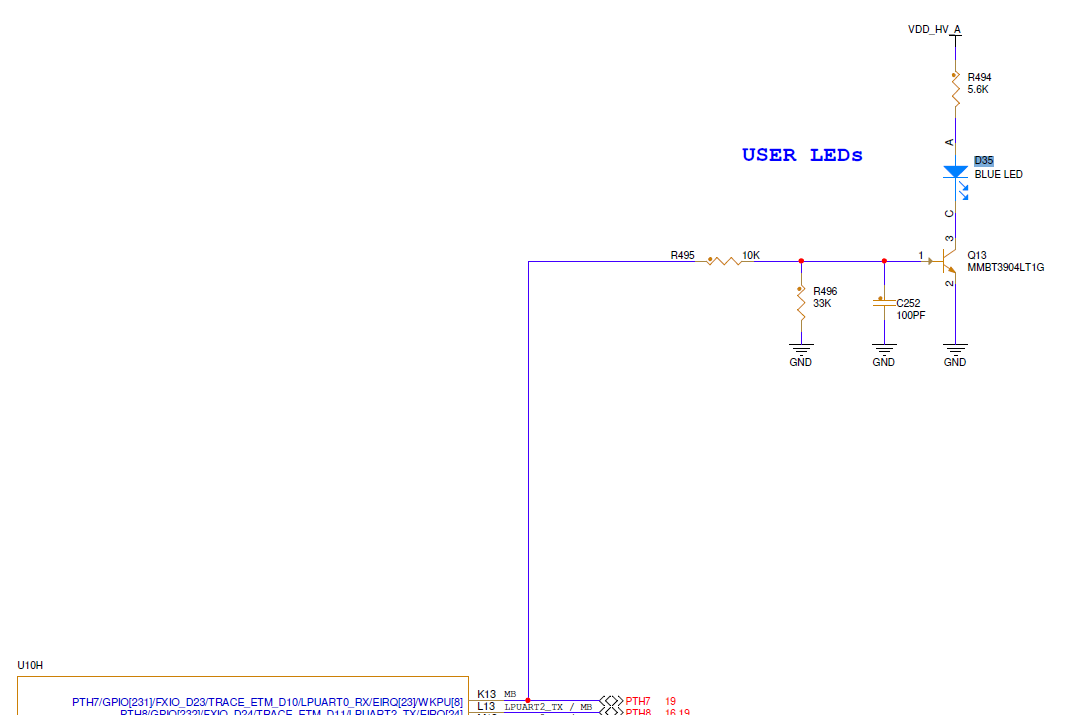

### Read SW7 button state for ClearFault signal

- Drag & drop a Dio block from **IO Blocks **Library and connect it to** ClearFault** input from **FaultLogic** subsystem.

- Double-click on Dio block and select the** Dio_ReadChannel** from the Function drop-down.

- From Channel drop-down, choose **USER_SW7 channel,** already configured in the external configuration tools project attached to the model. 

Thus, on each execution step the USER_SW7 button state will be read to assure clearing any faults that could occur in the Motor Control Current Monitoring system.

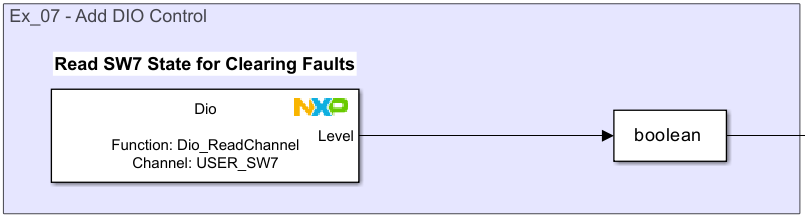

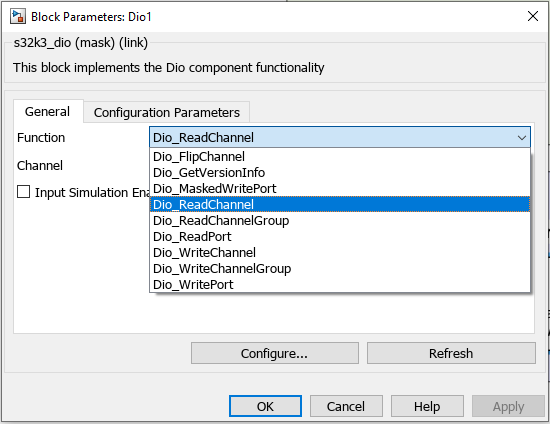   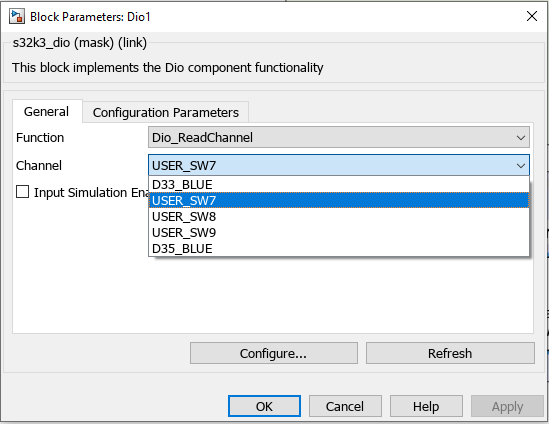

### Configure the DIO pins using S32 Configuration Tools

To manage the **ON/OFF D33/D35 LEDs** state for **OverLoad/OverCurrent Fault** status, the physical pins and Dio channels need to be configured, using **S32CT**. The following configuration has been already performed on the external **S32 Configuration Tools**, so please follow the steps below to observe the hardware settings.

- Double click on the **Dio** block and click on **Configure...** button. The **S32 Configuration Tools** will open the **S32K3_02Config.mex** file attached to the model.

- On the upper right side, click on **Pins** tool.                                                                                                                                                                                     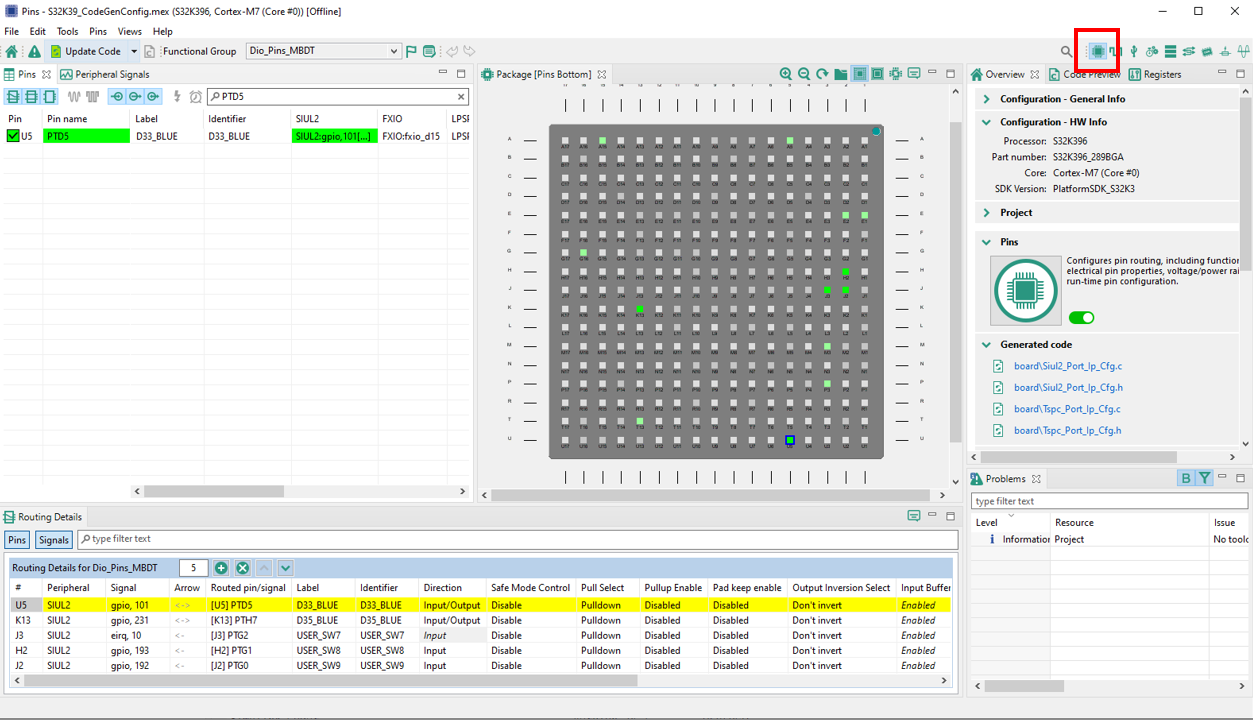

- The **Pins** tool, is designed to configure routing peripheral signals either to pins or to internal signals. In the image above, we can observe the PTD5, D33, routed as an output pin.

- Click on **Peripherals Tool. The Peripherals Tool **is designed to configure the initialization of the RTD drivers. Once the pin is routed in the Pins tools, the same pin needs also to be configured in the **Port** component of the S32 RTD drivers, to ensure the pin initialization at the MCAL level of RTD drivers. The **Port component** is tightly coupled with the **Pins tool**. In the image below, under **Port Configuration -> PortConfigSet -> PortContainer -> Dio_Pins**, the **USER_SW7** pin has been configured.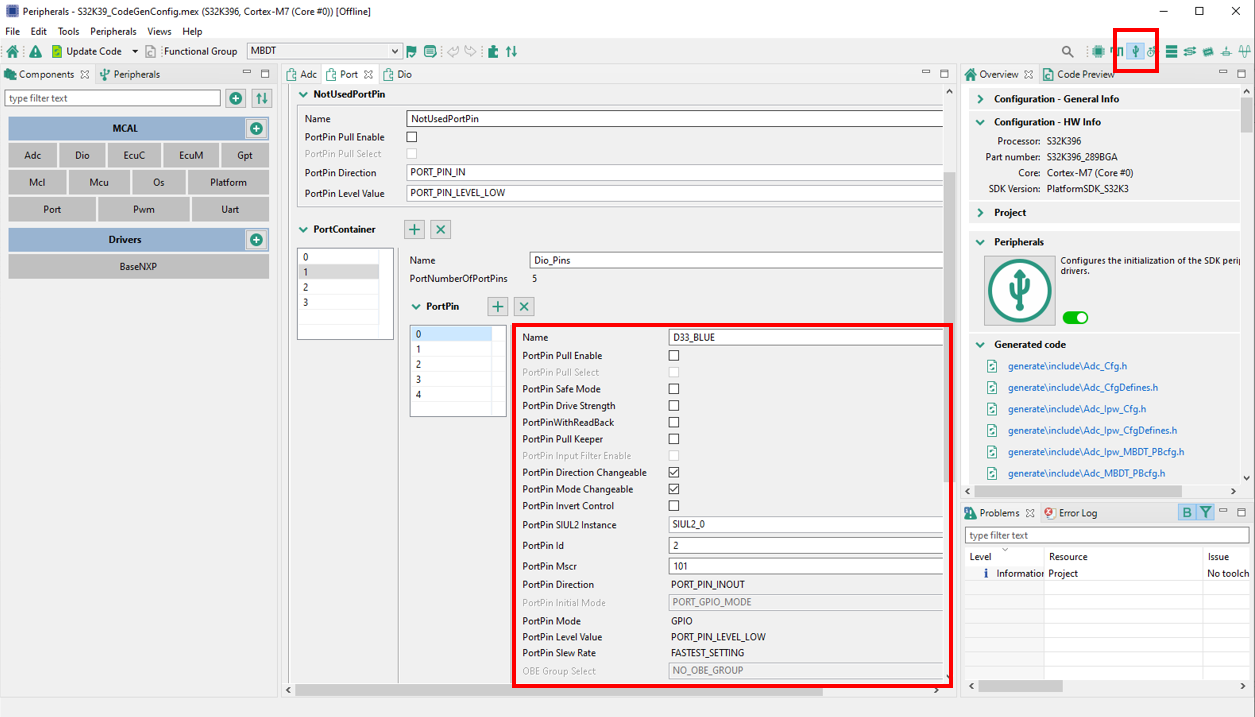

- Next, to have the **D33_LED **available in the Dio blocks drop-down in Simulink, same pins need to be configured for their Names inside the **Dio** component. Double Click on **Dio** component and click on **DioConfig** tab. Navigate to the DioPort entry 3 and check the **D33_BLUE**.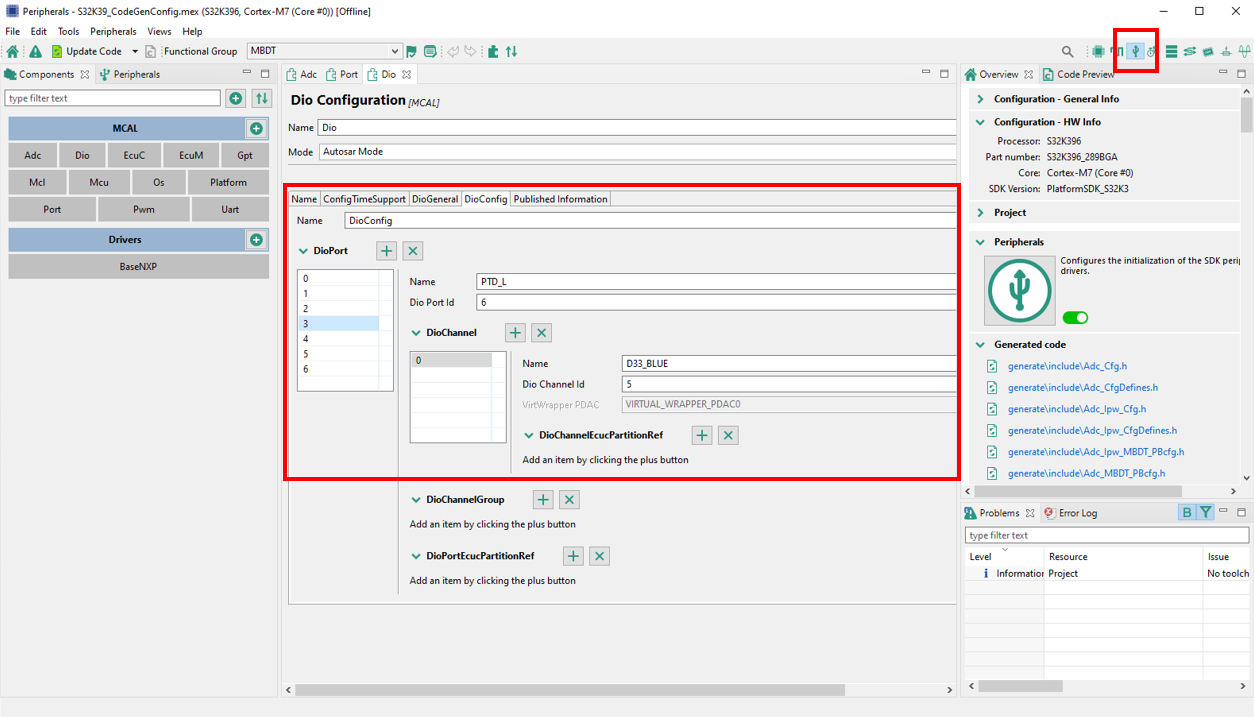

- As described earlier, the D33_BLUE is connected to **PTD5 -> PORTD:PIN5**. The **DioPort** for PTD is already configured, with the name** PTD_L **and **Dio** **Port Id** value equals to** 6. **At the MCU level,** PTD** is mapped on a 32-bit register, but the external configuration tools DioChannel Id can only support values between 0 and 15. So the **PTD** register is split in half, with the** PTD_H** covering the** PTD** bits range [16 - 31] and the** PTD_L **covering the **PTD** bits range [0 - 15].The DioPort Id value for** PTD_L** register is equal to **6** and for **PTD_H** register is equal to **7**.

- Applying the same logic from the point 6, if we were to configure the **PTD25**, then the pin control would be located in the **PTD_H (register 7) and the actual Dio Channel Id number, would have been 9 (25 modulo 16), because PTD_H and PTD_L are 16 bit registers.**

- Save and close the **S32 Configuration Tools**. 

- Back in the Dio block, press the** Refresh** button to update the external configuration tool settings into our Simulink model.

### Add D33 and D34 LEDS to hightlight the Fault statuse

- Drag & drop 2 **Dio** blocks from the Simulink Liberary Browser into our model.

- For each, select** Dio_WriteChannel** function and the **D33_BLUE** and **D35_BLUE** channel that has been configured using the external **S32 Configuration Tools**. 

- Connect the inputs of the **Dio** blocks to the **OverLoad_Actuate** and **OverCurrent_Actuate** outputs of the **Actuate D33 & D35 LEDs** subsystem.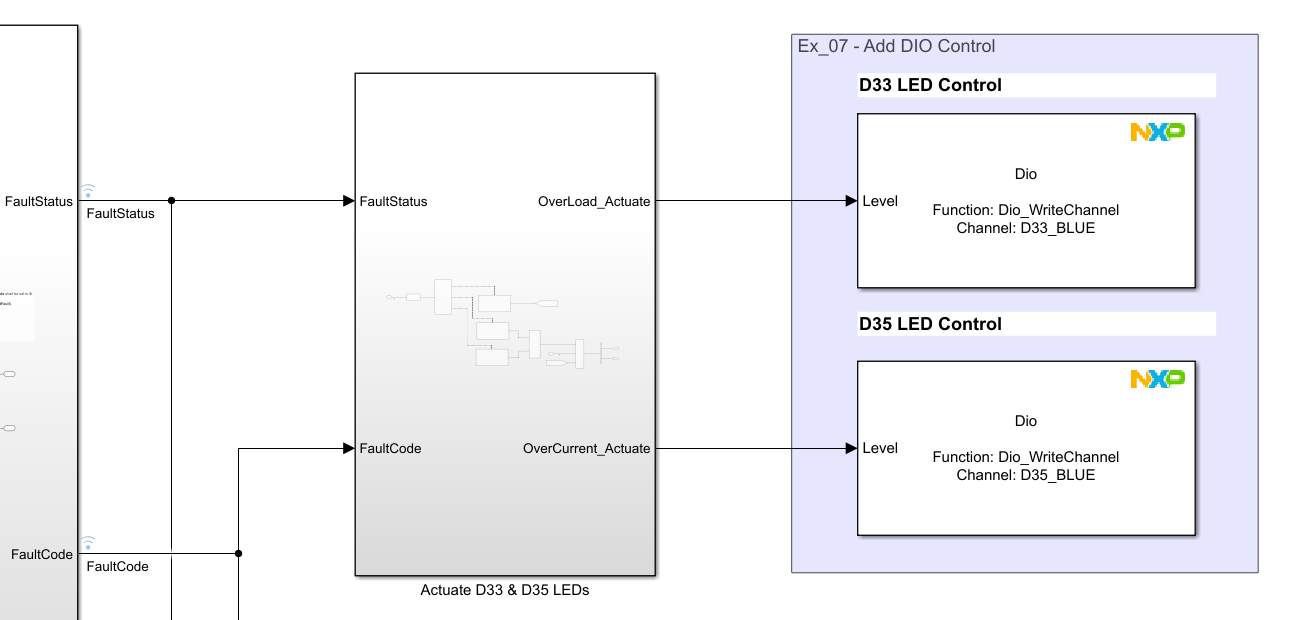

At this point, we have configured the **Dio** blocks that manages reading the state of **USER_SW7** push button for **ClearFault** signal and setting the state of the **OverLoad** and **OverCureent** for Fault status. 

Now you can **Build & Deploy the model** to visually check the **Dio** functionality.

In the next exercise the Pulse Width Motulation signal is used to control the D34 LED for showing the Fault Status. 

edit('Ex_08');